Demo code for Figure 2 of Idesis (2023) - A low dimensional embedding of brain dynamics enhances diagnostic accuracy and behavioral prediction in stroke

Written by: Sebastian Idesis - sebastian.idesis@gmail.com (June 2023)

Initialize script

clear all;close all;clc; %Close everything
nodes = 200; % Amount of nodes from the dataset
Isubdiag = find(tril(ones(nodes),-1)); %Upper triangle indexes needed later
addpath 'Functions'

Load regional time series

load data/ts.mat %Demo data (Taken from https://www.brainnetworkslab.com/coderesources)

Create fake data of other 3 subjects

amount_of_controls= 4; %Number for control subjects for demo
for subj = 1:amount_of_controls
    subject{subj}= (ts.*(randn(1200,200)))'; %original ts plus a small factor random amount to make every subject different
end

Calculate Complexity

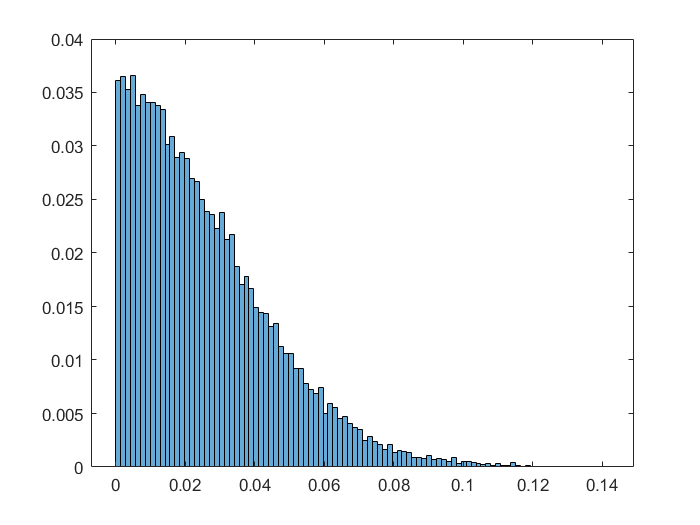

numBin=100; %Amount of Bins. See Reference paper for more information (Zamora-Lopez et al, 2016)
%https://link.springer.com/content/pdf/10.1038/srep38424.pdf

complexity_controls=zeros(amount_of_controls,1);
for subj = 1:amount_of_controls
    ts=subject{subj};
    ts(isnan(ts))=0;
    fc_temp=corrcoef(ts');
    [C_FC] = spatial_complexity(fc_temp,numBin);
    complexity_controls(subj)=C_FC;
end


complexity_avg=mean(complexity_controls);